## How to generate a sinusoidal signal?

We need to determine 2 parameters to make any type of signal:

- Number of data points that will be in the waveform (N)

- Sampling frequency (fs)

N = 1000;   % Number of data points
fs = 500;   % Sampling rate (sampling frequency)

Let's generate a 5 Hz sinusoidal signal:

## $\mathrm{sin}\left(\omega t\right)$ where $\omega$ is frequency in radians

## 
$$\omega \;=2\pi \textrm{f}$$


f = 5;
t = 0:1/fs:(N-1)/fs;    % Time vector
x = sin(2*pi*f*t);

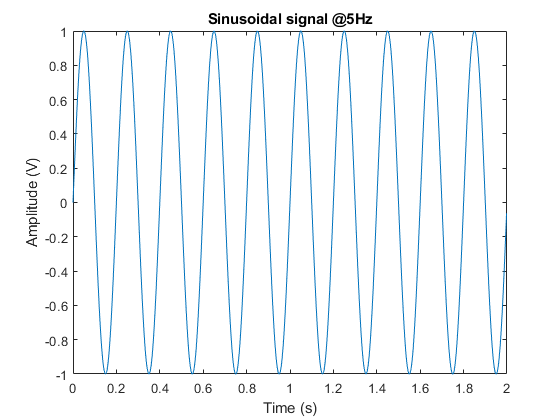

figure()
plot(t, x)
xlabel('Time (s)')
ylabel('Amplitude (V)')
title('Sinusoidal signal @5Hz')

Introduce a phase shift:

## 
$$\sin \left(\omega t+\theta \right)$$


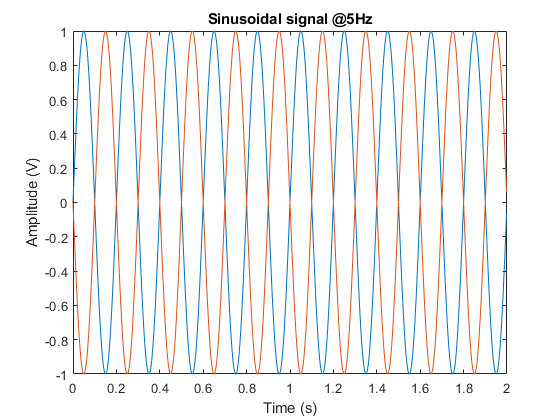

x2 = sin(2*pi*f*t + pi);
hold on;
plot(t, x2)
hold off;

## How to simulate noise?

- Most waveforms consist of signal plus noise mixed together

- Signal is the portion of waveform we are interested in, noise is everything else

- Often the goal of signal processing is separate signal from noise

Noise is usually represented as Gaussian white noise (uniformly distributed random numbers)

We can use "randn" function.

n = randn(5)

n = randn(1000,1);
mean(n)

ans = 0.0074

std(n)

ans = 0.9831

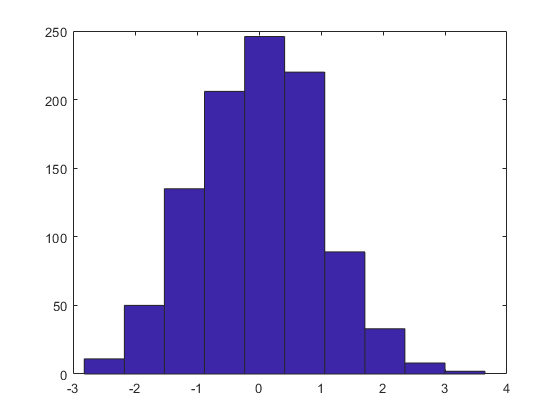

hist(n)

## How to simulate a noisy signal?

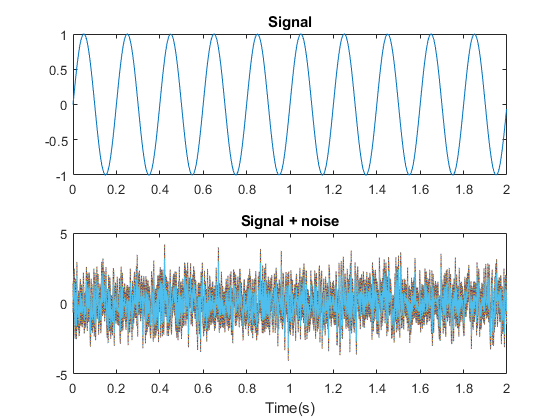

N = 1000;   % Number of data points
fs = 500;   % Sampling rate (sampling frequency)

f = 5;
t = 0:1/fs:(N-1)/fs;    % Time vector
x = sin(2*pi*f*t);
noise = randn(length(x),1);

noisy_x = x + noise; % There is a mistake here

figure;
subplot(211); plot(t, x); title('Signal')
subplot(212); plot(t, noisy_x); title('Signal + noise'); xlabel('Time(s)');

size(x)

ans =            1        1000


size(noise)

ans =         1000           1


## Signal-to-noise-ratio

- This is a relative term

- The amount of signal and noise prsent in a waveform is usually quantified by the SNR

- SNR: the ratio of signal to noise, both measured in root-mean-squared (RMS) amplitude

## 
$$\mathrm{SNR}=20\text{ }\mathrm{log}\left(\frac{{\mathrm{Signal}}_{\mathrm{rms}} }{{\mathrm{Noise}}_{\mathrm{rms}} }\right)\mathrm{dB}$$


- To convert from dB scale to linear scale:

## 
$${\mathrm{SNR}}_{\mathrm{linear}} ={10}^{\frac{\mathrm{dB}}{20}}$$


Example: Plot signals with varying amounts of added noise such that the SNRs are:

- 20 dB (RMS value of the signal is 10 times the RMS value of the noise)

- 10 dB

- 3 dB

- 0 dB

- -3 dB

- -10 dB

N = 500;   % Number of data points
fs = 500;   % Sampling rate (sampling frequency)

f = 10;
t = 0:1/fs:(N-1)/fs;    % Time vector
x = sin(2*pi*f*t);
x = x';
noise = randn(length(x),1);

x_rms = rms(x)

x_rms = 0.7071

noise_rms = rms(noise)

noise_rms = 1.0348

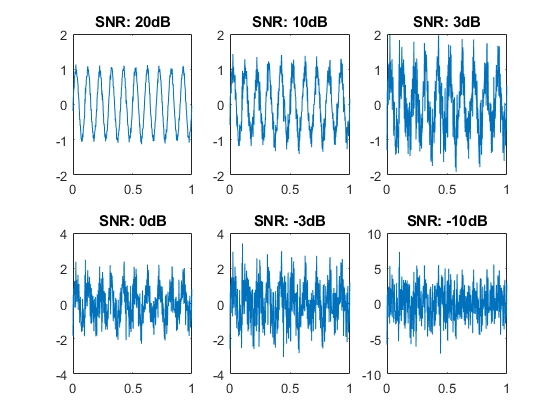

figure;
subplot(231); plot(t, x + noise*(x_rms/10^(20/20))); title('SNR: 20dB')
subplot(232); plot(t, x + noise*(x_rms/10^(10/20))); title('SNR: 10dB')
subplot(233); plot(t, x + noise*(x_rms/10^(3/20))); title('SNR: 3dB')
subplot(234); plot(t, x + noise*(x_rms/10^(0/20))); title('SNR: 0dB')
subplot(235); plot(t, x + noise*(x_rms/10^(-3/20))); title('SNR: -3dB')
subplot(236); plot(t, x + noise*(x_rms/10^(-10/20))); title('SNR: -10dB')